# Backtesting the trading strategy in just 8 lines of MATLAB code

Copyright 2017-2017 The MathWorks, Inc.

In this example, we use data from dowPortfolio.xlsx, whcih is shipped with Financial Toolbox™. You can see the data by executing "open('dowPortfolio.xlsx')".

prices = xlsread('dowPortfolio.xlsx');
returns = tick2ret(prices(:,1));
signal = 1*(rsindex(prices(:,1)) < 40) - 1*(rsindex(prices(:,1)) > 70);
portReturns = returns .* signal(1:end-1);
sharpeRatio = sharpe(portReturns,0)*sqrt(252)

sharpeRatio = 1.7603

portValues = ret2tick(portReturns);
maxdd = maxdrawdown(portValues)

maxdd = 0.0336

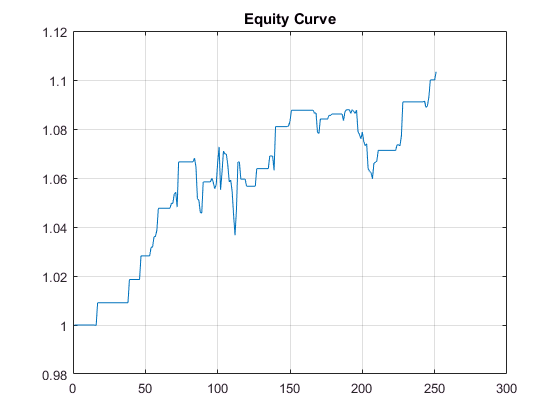

plot(portValues)